# Compare Spatial Information and Firing Rate

t-test p-value: 0.0032143


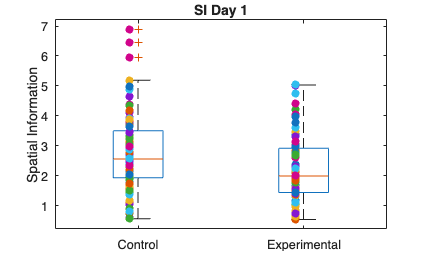

t-test p-value: 0.060947


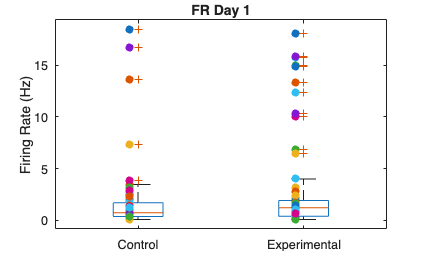

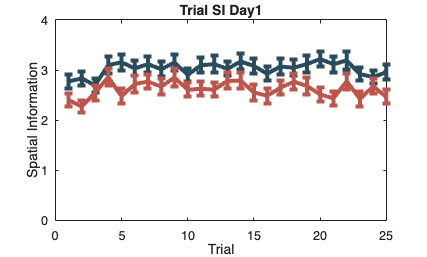


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2     pValue     
    {'(Intercept)'}        1472.5    1      3800    1.3997e-272
    {'group'      }        1.4998    1      3800        0.22078
    {'trial'      }        25.494    1      3800     4.6448e-07
    {'group:trial'}        10.221    1      3800         0.0014



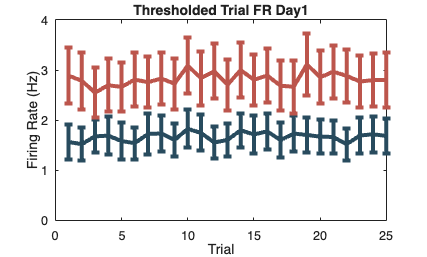


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat       DF1    DF2     pValue    
    {'(Intercept)'}          82.809    1      4021    1.3902e-19
    {'group'      }          23.178    1      4021    1.5309e-06
    {'trial'      }        0.028371    1      4021       0.86625
    {'group:trial'}         0.15878    1      4021        0.6903



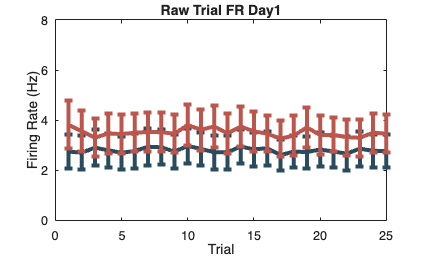

t-test p-value: 0.077022


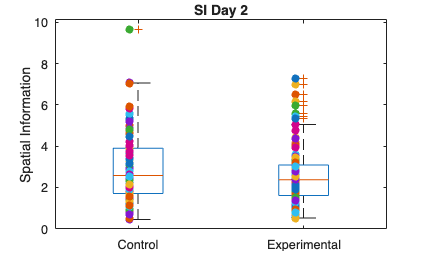

t-test p-value: 0.52097


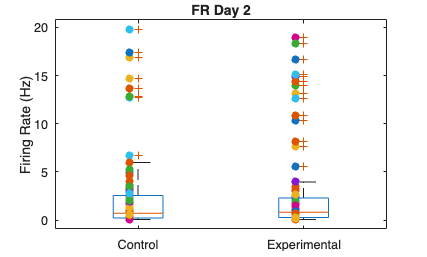

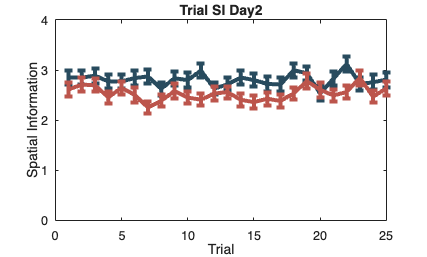


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat      DF1    DF2     pValue     
    {'(Intercept)'}         1641.3    1      4603    3.5467e-307
    {'group'      }          5.016    1      4603       0.025162
    {'trial'      }        0.35443    1      4603        0.55164
    {'group:trial'}        0.73881    1      4603        0.39009



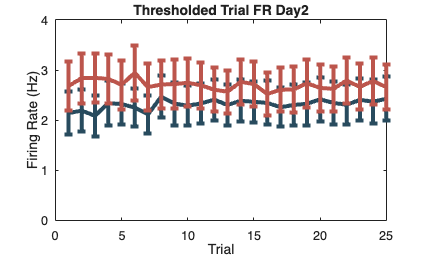


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat        DF1    DF2     pValue    
    {'(Intercept)'}           157.02    1      4996    1.7243e-35
    {'group'      }           1.8789    1      4996       0.17052
    {'trial'      }        0.0031966    1      4996       0.95491
    {'group:trial'}         0.030665    1      4996         0.861



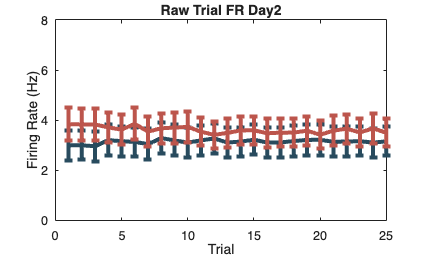

t-test p-value: 0.17464


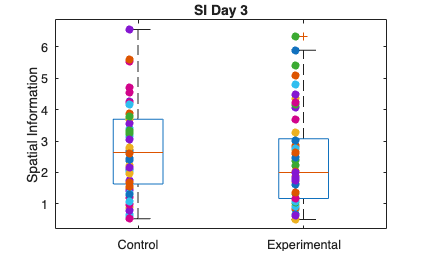

t-test p-value: 0.72068


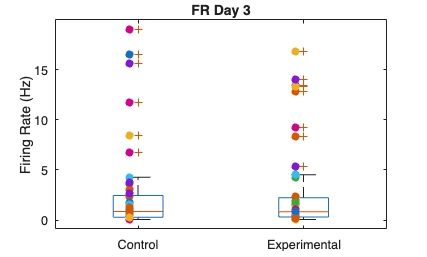

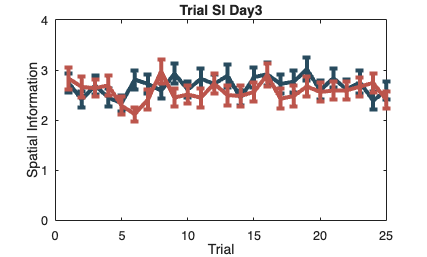


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat       DF1    DF2     pValue     
    {'(Intercept)'}          750.64    1      2125    8.7488e-142
    {'group'      }          2.5672    1      2125        0.10925
    {'trial'      }        0.014129    1      2125        0.90539
    {'group:trial'}         0.86641    1      2125        0.35206



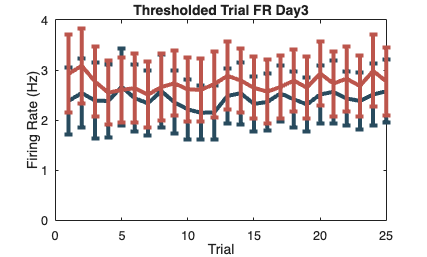


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat       DF1    DF2     pValue    
    {'(Intercept)'}          95.004    1      2496    4.6737e-22
    {'group'      }         0.52015    1      2496       0.47085
    {'trial'      }        0.053043    1      2496       0.81787
    {'group:trial'}        0.018672    1      2496       0.89132



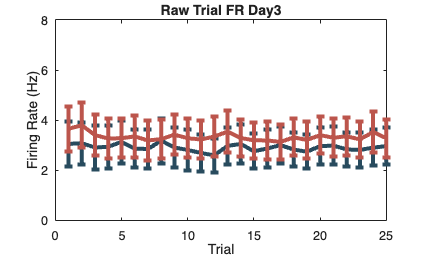

t-test p-value: 0.0018734


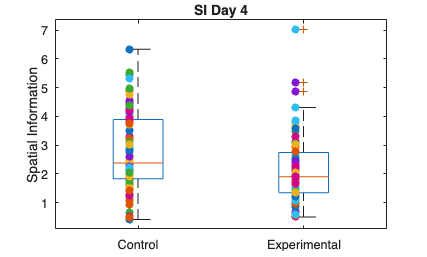

t-test p-value: 0.83372


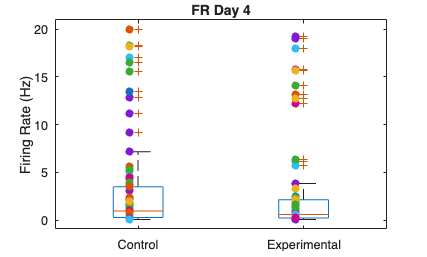

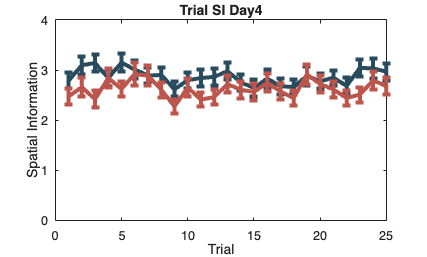


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat      DF1    DF2     pValue     
    {'(Intercept)'}         1337.8    1      3074    1.7273e-243
    {'group'      }         11.288    1      3074     0.00078942
    {'trial'      }        0.72404    1      3074        0.39489
    {'group:trial'}         2.1747    1      3074         0.1404



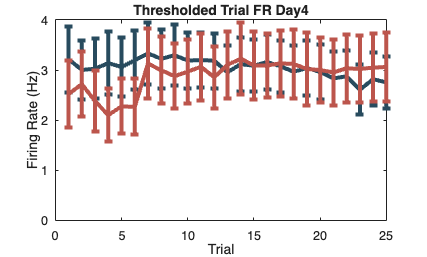


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat        DF1    DF2     pValue    
    {'(Intercept)'}           165.21    1      3846    4.7268e-37
    {'group'      }          0.29816    1      3846       0.58507
    {'trial'      }        0.0075952    1      3846       0.93056
    {'group:trial'}        0.0050898    1      3846       0.94313



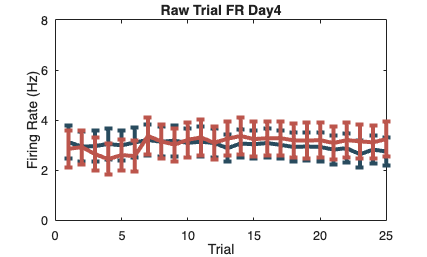

t-test p-value: 0.033944


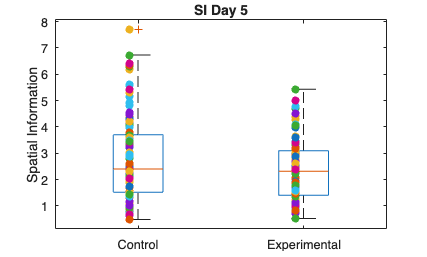

t-test p-value: 0.39482


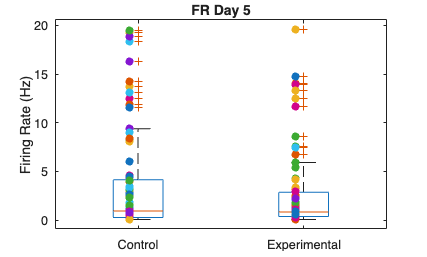

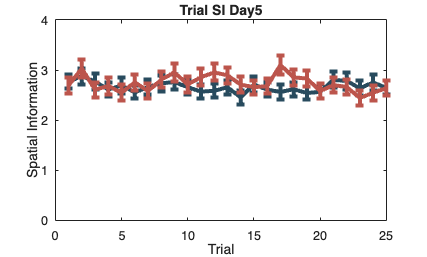


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat      DF1    DF2     pValue     
    {'(Intercept)'}         1337.2    1      3837    1.9274e-251
    {'group'      }         1.9612    1      3837        0.16147
    {'trial'      }        0.19378    1      3837        0.65981
    {'group:trial'}        0.56922    1      3837        0.45061



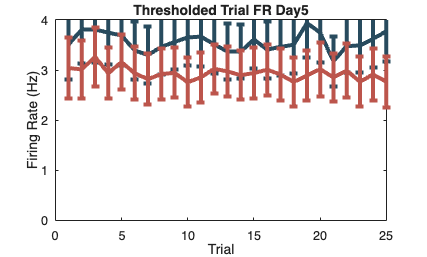


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat      DF1    DF2     pValue    
    {'(Intercept)'}         247.39    1      4396    2.8391e-54
    {'group'      }          1.854    1      4396       0.17338
    {'trial'      }        0.16407    1      4396       0.68546
    {'group:trial'}        0.37893    1      4396       0.53821



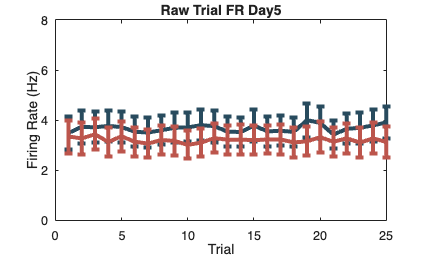

t-test p-value: 0.60533


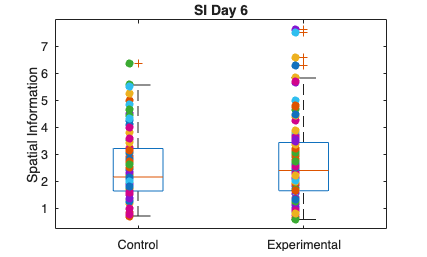

t-test p-value: 0.53823


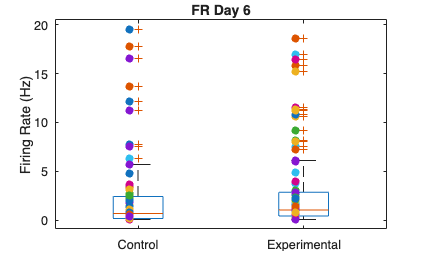

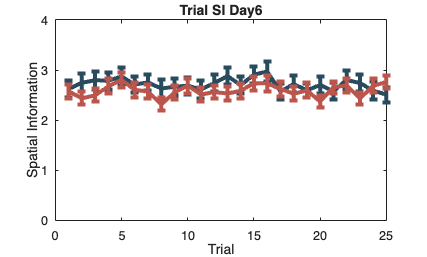


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat       DF1    DF2     pValue     
    {'(Intercept)'}          946.32    1      3408    1.3379e-183
    {'group'      }         0.86824    1      3408        0.35151
    {'trial'      }         0.20798    1      3408        0.64839
    {'group:trial'}        0.054764    1      3408        0.81499



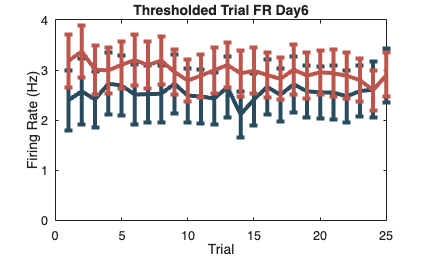


    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat         DF1    DF2     pValue    
    {'(Intercept)'}            124.14    1      4096    2.0044e-28
    {'group'      }            2.1574    1      4096       0.14196
    {'trial'      }          0.037899    1      4096       0.84566
    {'group:trial'}        0.00032801    1      4096       0.98555



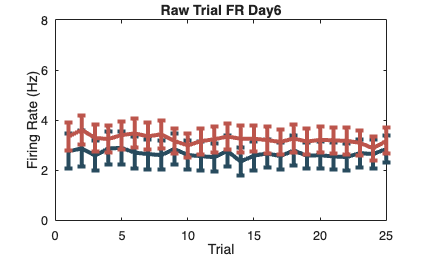

clear; close all; clc;

% Load Data 
animalID = [65622,63383,67330,67456,66922,65588,67324,67141];
data_path = fullfile(get_data_root(),'CompiledData');
load(fullfile(data_path,'CompiledSpatialStats.mat'));
save_path = fullfile(get_data_root(),'Figures/Ingvild/Ephys');

colors = {'#284B5E','#BC554C'}; % Control, Experimental
days = 6;
animals = numel(animalID);

% Indexing
experimental = find(genotype_idx == 2);
control = find(genotype_idx == 1);
cells = cellfun(@length,SI);
cell_numb = [sum(cells(:,control),'all'),sum(cells(:,experimental),'all')];

% Filter and Extract Metrics - NB: everything was QM filtered (including FR)
[si_thresh, sp_thresh, fr_thresh, fr_avr, si_trial_thresh] = extract_metrics(SI, sparsity, FR, si_trials, animals, days);

% Aggregate Firing Rates for Summary = wrong cell counts check! it is taking the trials
[~, ~, days_fr_cont, days_fr_exp] = aggregate_firing_rates(FR, fr_thresh, control, experimental, days);

% Plot Day-wise and Trial-wise Comparisons 
for d = 1:days
    plot_si_day(si_thresh, d, control, experimental, colors, save_path);
    plot_fr_day(fr_thresh, d, control, experimental, colors, save_path);
    % plot_sp_day(sp_thresh, d, control, experimental, colors, save_path);
    plot_trial_si(si_trial_thresh, d, control, experimental, colors, save_path);
    plot_trial_fr(FR, d, control, experimental, colors, save_path);
end

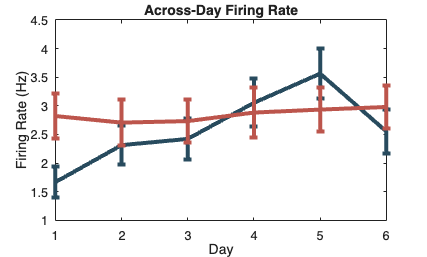


% Plot Across Days 
plot_across_days(days_fr_cont, days_fr_exp, colors,save_path);

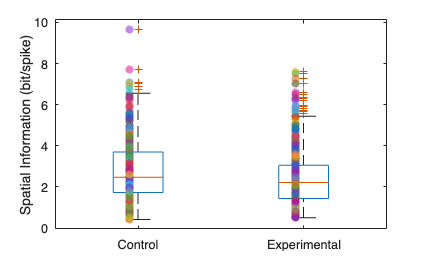

ans = "/Volumes/quattrocolo/crhip/ingvild/Analysis/Figures/Ingvild/Ephys/SI/Comparison/SI_box.svg"

t-test p-value: 3.2898e-05


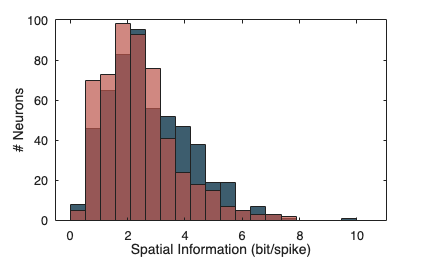


% Plot All Days
label_text = 'Spatial Information (bit/spike)';
edges = linspace(0,10.5,21);
plot_group_comparison(SI, control, experimental, cell_numb, edges, colors, label_text, label_text);

label_text = 'Sparsity';

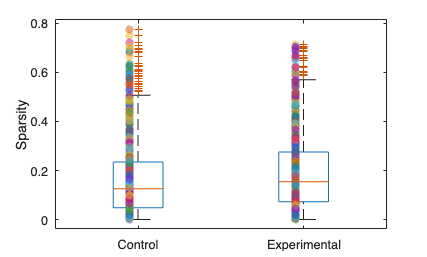

ans = "/Volumes/quattrocolo/crhip/ingvild/Analysis/Figures/Ingvild/Ephys/SI/Comparison/Sparsity_box.svg"

t-test p-value: 0.0099076


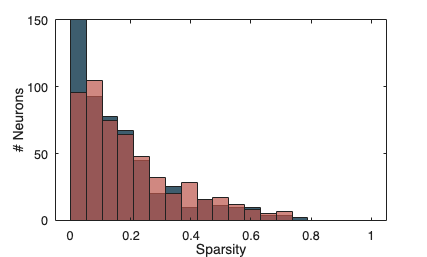

edges2 = linspace(0,1,20);
plot_group_comparison(sparsity, control, experimental, cell_numb, edges2, colors, label_text, label_text);

% label_text = 'Spatial info rate (bit/s)';
% edges2 = linspace(0,8,20);

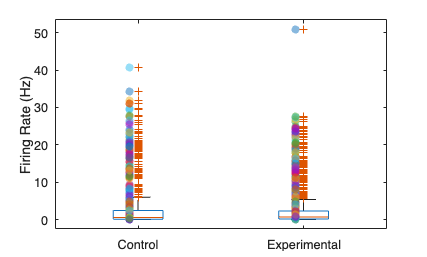

ans = "/Volumes/quattrocolo/crhip/ingvild/Analysis/Figures/Ingvild/Ephys/FR/Comparison/FR_box.svg"

t-test p-value: 0.44744


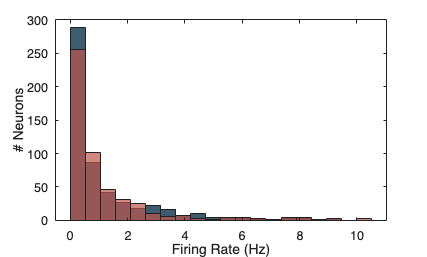

% plot_group_comparison(si_rate, control, experimental, cell_numb, edges2, colors, label_text, label_text);

save_fr = fullfile(save_path,'FR/Comparison');
label_text = 'Firing Rate (Hz)';
save_tag = 'FR';
edges = linspace(0,10.5,21);
plot_group_comparison(fr_avr, control, experimental, cell_numb, edges, colors, label_text, label_text);

label_x = 'Firing Rate (Hz)';
label_y = 'SI (bit/spike)';
save_tag = 'FRvSI';

plot_si_vs_fr(SI,fr_avr, control, experimental, cell_numb, colors, save_fr, label_y, label_x, save_tag);



for a = 1:animals

Error using cell2mat (line 36)
cell2mat does not support cell arrays containing cell arrays.

Error in plot_si_vs_fr (line 22)
    si_all_cont = cell2mat(flat_cont);

    spatial_info = cell2mat(SI(:,a)');
    si_avr(1,a) = mean(spatial_info,"omitmissing");
end

si_grouped = [si_avr(control)',si_avr(experimental)'];
[~,p] = ttest2(si_grouped(:,1),si_grouped(:,2));

figure
boxplot(si_grouped,{'Control','Experimental'})
hold on
scatter(1,si_avr(control), 'filled', 'jitter','on','jitterAmount',0.08)
scatter(2,si_avr(experimental), 'filled', 'jitter','on','jitterAmount',0.08)
ylim([0 3.1])
yticks(0:1:3)
ylabel('Spatial Information (bit/spike)')
title('Animal averages')
save_figure(fullfile(get_data_root(),'Figures/Ingvild/Ephys/SI/Comparison'),'SI_animal_average');

function [si_out, sp_out, fr_thresh, fr_avr, si_trial_out] = extract_metrics(SI, sparsity, FR, si_trials, animals, days)
    si_out = cell(days, animals);
    fr_thresh = cell(days, animals);
    fr_avr = cell(days, animals);
    si_trial_out = cell(days, animals);
    sp_out = cell(days, animals);
    for a = 1:animals
        for d = 1:days
            if isempty(SI{d,a})
                continue
            end
            fr = mean(cellfun(@mean, FR{d,a}), 1);
            valid = fr >= 0.05 & fr < 20;
            fr_thresh{d,a} = fr(valid);
            fr_avr{d,a} = fr;
            si_out{d,a} = SI{d,a};
            si_trial_out{d,a} = si_trials{d,a};
            sp_out{d,a} = sparsity{d,a};
        end
    end
end

function [cell_counts, max_cells, fr_cont_mat, fr_exp_mat] = aggregate_firing_rates(FR, fr_thresh, control, experimental, days)
    cell_counts = cellfun(@length, FR);
    max_cells = max([sum(cell_counts(:,control),2); sum(cell_counts(:,experimental),2)],[],'all');
    fr_cont_mat = nan(days, max_cells);
    fr_exp_mat = nan(days, max_cells);
    for d = 1:days
        fr_cont = cell2mat(fr_thresh(d,control));
        fr_exp = cell2mat(fr_thresh(d,experimental));
        fr_cont_mat(d,1:numel(fr_cont)) = fr_cont;
        fr_exp_mat(d,1:numel(fr_exp)) = fr_exp;
    end
end

function plot_si_day(si_data, day, control, experimental, colors,save_path)
    save_p = fullfile(save_path, sprintf('Day%d',day));
    si_cont = cell2mat(si_data(day,control));
    si_exp = cell2mat(si_data(day,experimental));
    group_name = {'Control','Experimental'};
    grouped_si = nan(2,max(numel(si_cont),numel(si_exp)));
    grouped_si(1,1:numel(si_cont)) = si_cont;
    grouped_si(2,1:numel(si_exp)) = si_exp;
    [~,p] = ttest2(grouped_si(1,:), grouped_si(2,:));
    % p = ranksum(grouped_si(1,:), grouped_si(2,:));
    disp(['t-test p-value: ' num2str(p)])
    figure; boxplot(grouped_si',group_name); hold on;
    scatter(1, grouped_si(1,:), 'filled', 'jitter','on','jitterAmount',0.08);
    scatter(2, grouped_si(2,:), 'filled', 'jitter','on','jitterAmount',0.08);
    ylabel('Spatial Information'); title(sprintf('SI Day %d', day));
    save_figure(save_p, sprintf('SI Day%d', day));
end

function plot_sp_day(sp_data, day, control, experimental, colors,save_path)
    save_p = fullfile(save_path, sprintf('Day%d',day));
    sp_cont = cell2mat(sp_data(day,control));
    sp_exp = cell2mat(sp_data(day,experimental));
    group_name = {'Control','Experimental'};
    grouped_si = nan(2,max(numel(sp_cont),numel(sp_exp)));
    grouped_si(1,1:numel(sp_cont)) = sp_cont;
    grouped_si(2,1:numel(sp_exp)) = sp_exp;
    figure; boxplot(grouped_si',group_name); hold on;
    scatter(1, grouped_si(1,:), 'filled', 'jitter','on','jitterAmount',0.08);
    scatter(2, grouped_si(2,:), 'filled', 'jitter','on','jitterAmount',0.08);
    ylabel('Sparsity'); title(sprintf('Sparsity Day %d', day));
    save_figure(save_p, sprintf('Sparsity Day%d', day));
end

function plot_fr_day(fr_data, day, control, experimental, colors,save_path)
    save_p = fullfile(save_path,'Thresholded');
    fr_cont = cell2mat(fr_data(day,control));
    fr_exp = cell2mat(fr_data(day,experimental));
    group_name = {'Control','Experimental'};
    grouped_fr = nan(2,max(numel(fr_cont),numel(fr_exp)));
    grouped_fr(1,1:numel(fr_cont)) = fr_cont;
    grouped_fr(2,1:numel(fr_exp)) = fr_exp;
    [~,p] = ttest2(grouped_fr(1,:), grouped_fr(2,:));
    % p = ranksum(grouped_fr(1,:), grouped_fr(2,:));
    disp(['t-test p-value: ' num2str(p)])
    figure; boxplot(grouped_fr',group_name); hold on;
    scatter(1, grouped_fr(1,:), 'filled', 'jitter','on','jitterAmount',0.08);
    scatter(2, grouped_fr(2,:), 'filled', 'jitter','on','jitterAmount',0.08);
    ylabel('Firing Rate (Hz)'); title(sprintf('FR Day %d', day));
    save_figure(save_p, sprintf('FR Day%d', day));
end

function plot_trial_si(si_trial, day, control, experimental, colors,save_path)
    save_p = fullfile(save_path, sprintf('Day%d',day));
    cont = cell2mat(si_trial(day,control)');
    exp = cell2mat(si_trial(day,experimental)');
    figure;
    errorbar(mean(cont,'omitnan'), SE(cont), 'LineWidth', 3, 'Color', colors{1}); hold on;
    errorbar(mean(exp,'omitnan'), SE(exp), 'LineWidth', 3, 'Color', colors{2});
    ylabel('Spatial Information'); xlabel('Trial'); ylim([0 4]);
    title(sprintf('Trial SI Day%d', day));
    save_figure(save_p, sprintf('Trial SI Day%d', day));

    % Build table
    group = [repmat("control", numel(cont), 1); repmat("experimental", numel(exp), 1)];
    trial = repmat((1:25)', size(cont,1) + size(exp,1), 1);
    si = [cont(:); exp(:)];
    neuron = (1:length(si))'; % neuron IDs
    
    T = table(si, group, trial, neuron);
    
    % LME: SI ~ group * trial + (1|neuron)
    lme = fitlme(T, 'si ~ group*trial + (1|neuron)');
    disp(anova(lme));
end

function plot_trial_fr(FR, day, control, experimental, colors,save_path)
    grouped_cont = cat(2, FR{day,control});
    grouped_exp = cat(2, FR{day,experimental});
    trial_cont = cellfun(@mean, grouped_cont);
    trial_exp = cellfun(@mean, grouped_exp);

    % Thresholded
    mean_fr_cont = mean(trial_cont);
    mean_fr_exp = mean(trial_exp);
    idx_cont = mean_fr_cont >= 0.05 & mean_fr_cont < 20;
    idx_exp = mean_fr_exp >= 0.05 & mean_fr_exp < 20;
    fr_cont_thresh = trial_cont(:, idx_cont);
    fr_exp_thresh = trial_exp(:, idx_exp);

    figure;
    errorbar(mean(fr_cont_thresh,2,'omitnan'), SE(fr_cont_thresh'), 'LineWidth', 3, 'Color', colors{1}); hold on;
    errorbar(mean(fr_exp_thresh,2,'omitnan'), SE(fr_exp_thresh'), 'LineWidth', 3, 'Color', colors{2});
    ylabel('Firing Rate (Hz)'); xlabel('Trial'); ylim([0 4]);
    title(sprintf('Thresholded Trial FR Day%d', day));
    save_figure(fullfile(save_path,'Thresholded'), sprintf('Trial FR Thresholded Day%d', day));
    
    cont = fr_cont_thresh';
    exp = fr_exp_thresh';
    % Build table
    group = [repmat("control", numel(cont), 1); repmat("experimental", numel(exp), 1)];
    trial = repmat((1:25)', size(cont,1) + size(exp,1), 1);
    fr = [cont(:); exp(:)];
    neuron = (1:length(fr))'; % neuron IDs

    T = table(fr, group, trial, neuron);

    % LME: SI ~ group * trial + (1|neuron)
    lme = fitlme(T, 'fr ~ group*trial + (1|neuron)');
    disp(anova(lme));

    % Raw
    figure;
    errorbar(mean(trial_cont','omitnan'), SE(trial_cont'), 'LineWidth', 3, 'Color', colors{1}); hold on;
    errorbar(mean(trial_exp','omitnan'), SE(trial_exp'), 'LineWidth', 3, 'Color', colors{2});
    ylabel('Firing Rate (Hz)'); xlabel('Trial'); ylim([0 8]);
    title(sprintf('Raw Trial FR Day%d', day));
    save_figure(save_path, sprintf('Trial FR Raw Day%d', day));
end

function plot_across_days(fr_cont, fr_exp, colors,save_path)
    figure;
    errorbar(mean(fr_cont','omitnan'), SE(fr_cont'), 'LineWidth', 3, 'Color', colors{1}); hold on;
    errorbar(mean(fr_exp','omitnan'), SE(fr_exp'), 'LineWidth', 3, 'Color', colors{2});
    ylabel('Firing Rate (Hz)'); xlabel('Day');
    title('Across-Day Firing Rate');
    save_figure(save_path, 'Across Days FR');
end


